## Experiment 6

### William Watkins

### 4 Feb 22

#### Clean Up

clear all
close all
clc

#### Problem 1

Spin_0p1_3  = load('Data/SpinModule_SysID_0p1Hz_3Hz_10Amp_50Step');
Spin_0p1_15 = load('Data/SpinModule_SysID_0p1Hz_15Hz_10Amp_50Step');
Spin_0p3_10 = load('Data/SpinModule_SysID_0p3Hz_10Hz_10Amp_50Step');
Spin_1_4    = load('Data/SpinModule_SysID_1Hz_4Hz_10Amp_50Step');
Spin_4_15   = load('Data/SpinModule_SysID_4Hz_15Hz_10Amp_50Step');

Plotting the frequency responses.

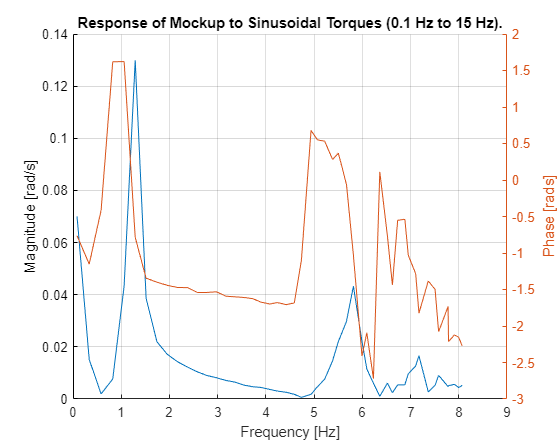

figure('Position', [200 200 1000 800]);
title('Response of Mockup to Sinusoidal Torques (0.1 Hz to 15 Hz).');
xlabel('Frequency [Hz]');
ylabel('Magnitude [rad/s]');
hold on;
grid on;
plot(Spin_0p1_15(1:end-1,1),Spin_0p1_15(1:end-1,2));
yyaxis right
ylabel('Phase [rads]');
plot(Spin_0p1_15(1:end-1,1),Spin_0p1_15(1:end-1,3));

These graphs don't give a very good insight to what is going on.  The resonant frequency was visually identified during the test as ocurring around 1.4 Hz, so a test focusing on that region was run.

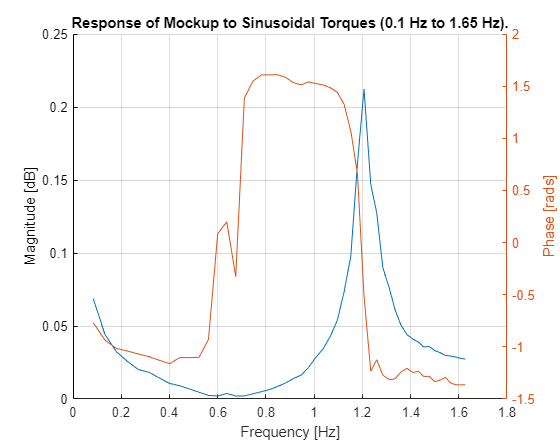

figure('Position', [200 200 1000 800]);
title('Response of Mockup to Sinusoidal Torques (0.1 Hz to 1.65 Hz).');
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
hold on;
grid on;
plot(Spin_0p1_3(1:end-1,1),Spin_0p1_3(1:end-1,2));
yyaxis right
ylabel('Phase [rads]');
plot(Spin_0p1_3(1:end-1,1),Spin_0p1_3(1:end-1,3));

We can see in this plot that the resonance frequency does occur at approximately 1.2 Hz, which corresponds to the visual observations in class.  The anti-resonance frequency occurs around 0.7 Hz.

#### Problem 2/3/4

The values for the spacecraft mockup are estimated below.

m1 = .05; % [kg]
m2 = m1;
l1 = 0.34; % [m]
l2 = l1;
r = 0.23; % [m]
Jb = 0.1;
K1 = 1000;
K2 = K1;

Using the State Space Method in class, the following A, B, C, and D matrices were determined.

A = [0 -1/(m1*l1) 0 0 0;
     K1/(l1+r) 0 0 0 0;
     0 0 0 -1/(m2*l2) 0;
     0 0 K2/(l2+r) 0 0;
     0 -1/Jb 0 -1/Jb 0];
B = [0;0;0;0;1/Jb];
C = [0 0 0 0 1];
D = [0];

Where x1 is vm1, x2 is tau1, x3 is vm2, x4 is tau2, and x5 is omeagab.

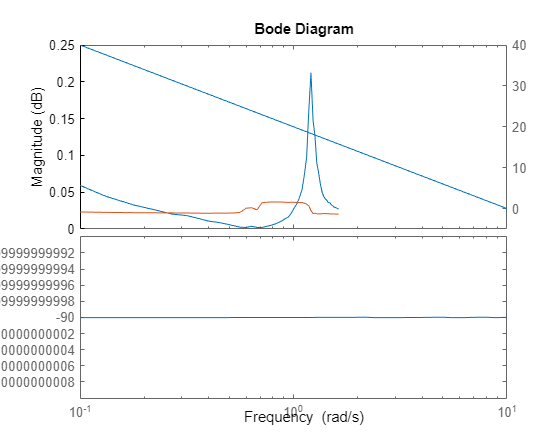

sys = ss(A, B, C, D);
[H, wout] = freqresp(sys);
[b,a] = ss2tf(A, B, C, D);
h = tf(b,a);
bode(h,{0.1 10});

As we can see, the magnitude (blue curve on top) of the response in this plot corresponds extremely well with the empirical data that was taken in the lab.  The peak, corresponding to the resonance frequency, occurs around 1.2 Hz, and the anti-resonance frequency is roughly 0.7 Hz.  Surprisingly, this was the first set of values that was estimated, and no additional fiddling was required.  I am not sure why the plot stops are ~1.8Hz, but the resonance and anti-resonance frequencies are clearly shown here.